KNN

% Load the necessary data if not already in the workspace
load('trainingSet.mat'); % XTrain, YTrain
load('validationSet.mat'); % XTest, YTest

knnModel = fitcknn(XTrain, YTrain, 'NumNeighbors', 5);


% Predict the labels of the validation set
[YPred, scores] = predict(knnModel, XTest);


% Convert YPred to categorical if YTest is categorical
YPred = categorical(YPred);

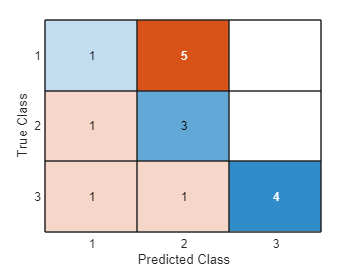



% Evaluate the classifier
confMat = confusionmat(YTest, YPred);
confusionchart(confMat);

accuracy = sum(YTest == YPred) / numel(YTest);
disp(['Accuracy: ', num2str(accuracy)]);

Accuracy: 0.5
